Importing Covid'19 from JHU CSSEIG.

confirmed = loadData('confirmed');
deaths = loadData('deaths');
recovered = loadData('recovered');

region = 12; % Queensland
t = 12:width(confirmed);
t-11

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


qlpop = 5072000; 
s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t};
i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t};
r1 = deaths{region,t} + recovered{region,t};

i0 = confirmed{region,t}

i0 =      1     3     2     3     2     2     3     3     4     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     9     9     9    11    11    13    13    13    15    15    18    20    20    35    46    61    68    78    94



t = 1:length(s1)-1;
M = transpose([s1; i1; r1;]);
M = [transpose(t) M(1:end-1,:) M(1:end-1,1)-M(2:end,1) M(2:end,3)-M(1:end-1,3)]

M =            1     5071999           1           0           2           0
           2     5071997           3           0          -1           0
           3     5071998           2           0           1           0
           4     5071997           3           0          -1           0
           5     5071998           2           0           0           0
           6     5071998           2           0           1           0
           7     5071997           3           0           0           0
           8     5071997           3           0           1           0
           9     5071996           4           0           1           0
          10     5071995           5           0           0           0


dS = [M(:,1:3), M(:,5)]

dS =            1     5071999           1           2
           2     5071997           3          -1
           3     5071998           2           1
           4     5071997           3          -1
           5     5071998           2           0
           6     5071998           2           1
           7     5071997           3           0
           8     5071997           3           1
           9     5071996           4           1
          10     5071995           5           0


dS = dS(dS(:,4)>0,:)

dS =            1     5071999           1           2
           3     5071998           2           1
           6     5071998           2           1
           8     5071997           3           1
           9     5071996           4           1
          23     5071995           5           1
          31     5071994           4           4
          34     5071990           8           2
          36     5071988          10           9
          39     5071979           5           2


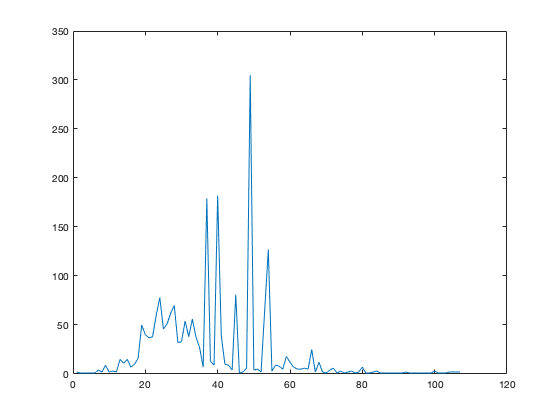

plot(dS(:,4))


beta = [dS(:, 1) (dS(:,4)*qlpop)./(dS(:,2).*dS(:,3))]

beta =     1.0000    2.0000
    3.0000    0.5000
    6.0000    0.5000
    8.0000    0.3333
    9.0000    0.2500
   23.0000    0.2000
   31.0000    1.0000
   34.0000    0.2500
   36.0000    0.9000
   39.0000    0.4000



rs = randsample(1:107, 75)

rs =     33     1     5    15    68    94    39    90    65    54    31    79    78    14    29   105    26    53    20    98    21   103    42    60    36    49    55    89    80    25    47    17    96    85    84    75   104    66    22    12    28    24   100    27    63    30    99    37     6    76


bfun = @(x, xdata)(-x(1).*xdata.^x(2))+(-x(4) + (x(5)+xdata).^x(3))

bfun = function_handle with value:
    @(x,xdata)(-x(1).*xdata.^x(2))+(-x(4)+(x(5)+xdata).^x(3))


fbfun = lsqcurvefit(bfun, [0, 0, 0, 0, 0], beta(rs,1), beta(rs, 2))


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


fbfun =    28.5485    0.0005   -0.4053  -28.6675   -0.1116


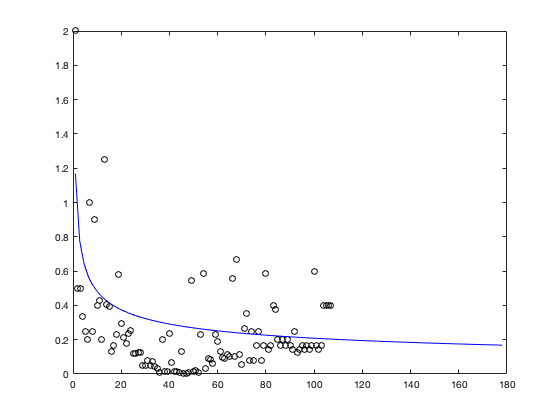

plot(1:107, beta(:,2), 'ko', times, bfun(fbfun,times),'b-')

mean((-dS(:,4)*qlpop)./(dS(:,2).*dS(:,3)))

ans = -0.2391

beta = [beta bfun(fbfun, beta(:,1))]

beta =     1.0000    2.0000    1.1682
    3.0000    0.5000    0.7541
    6.0000    0.5000    0.5811
    8.0000    0.3333    0.5226
    9.0000    0.2500    0.5005
   23.0000    0.2000    0.3559
   31.0000    1.0000    0.3195
   34.0000    0.2500    0.3090
   36.0000    0.9000    0.3027
   39.0000    0.4000    0.2940


dS(:, 3:4)

ans =      1     2
     2     1
     2     1
     3     1
     4     1
     5     1
     4     4
     8     2
    10     9
     5     2


(bfun(fbfun, dS(:,1)).*(dS(:,2)).*dS(:, 3))/qlpop

ans =     1.1682
    1.5082
    1.1623
    1.5678
    2.0020
    1.7794
    1.2779
    2.4720
    3.0268
    1.4702


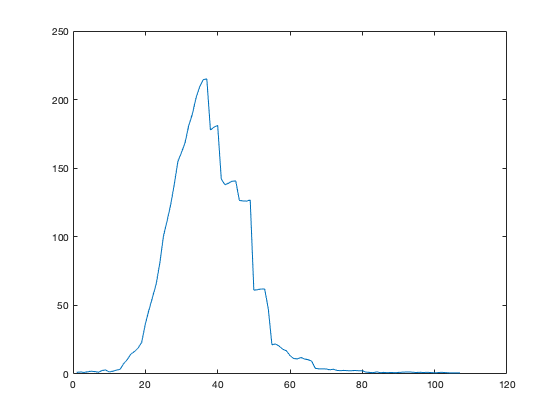

plot((bfun(fbfun, dS(:,1)).*(dS(:,2)).*dS(:, 3))/qlpop)

plot(dS(:,4))

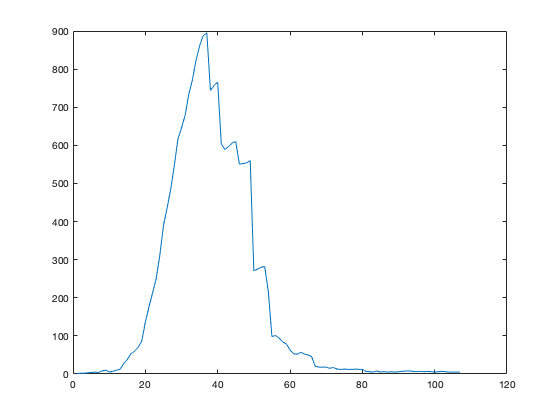

plot(dS(:,3))


fun=@(x,xdata)x(1)*1*exp(x(2)*xdata)./(x(1)+1*(exp(x(2)*xdata)-1))
times = linspace(M(1, 1),M(end, 1));
lss = lsqcurvefit(fun,[1, .001], 1:length(i0), i0)

plot(1:length(i0), i0, 'ko',times, fun(lss,times),'b-')

plot(abs(dS(:,4)))

% lsfun=@(x, xdata)-x(1).*xdata(1).*xdata(2)./qlpop
% lsfun=@(x,xdata)(x(1)*xdata(1)/qlpop*xdata(2))-x(2)*xdata(2);
% lss = lsqcurvefit(fun,(.35), dS(:,2:3), dS(:,4))

size(dS(:, 4))
size(dS(:,2:3))

sfun=@(x,xdata)(x(1)*xdata(1)*exp(-x(1))/qlpop*xdata(2))-x(2)*xdata(2);
lsfun([.387, .001], [dS(:,2) dS(:,3)])
lss = lsqcurvefit(lsfun, [.05, .141], [dS(:,2) dS(:,3)], abs(dS(:, 4)))

plot(1:length(dS), abs(dS(:, 4)), 'ko', times, fun(lss,times),'b-')

lsfun=@(x, xdata)(-x(1).* xdata(:, 1).* xdata(:, 2)./qlpop);

dSdt = @(beta, par)-beta.*par(1, 2).*par(1, 1)
ode45(@(t,y) dSdt(y, [par(:,2) par(:,3)]), 1:length(i0)-1, 0)


commandhistory
%fminsearch(@(par) , [.387 .33 qlpop]) 

function dCdt = odeFun(~,C,par)
%ODEFUN SIR model

    % unpack parameters
    beta  = par(1);
    gamma = par(2);
    N     = par(3);
    I0    = par(4);
    
    % set temp. vars
    c0    = I0/N;
    c     = C/N;

    % setup equation
    %dCdt = N*(1 - c)*(beta*c + gamma*log((1 - c)/(1 - c0)));
      dCdt = gamma*N*(1 - c - (1 - c0)*exp(-beta*c/gamma));
end

